clc;
clear;

## الف: تابع چگالی احتمال و رسم آن 

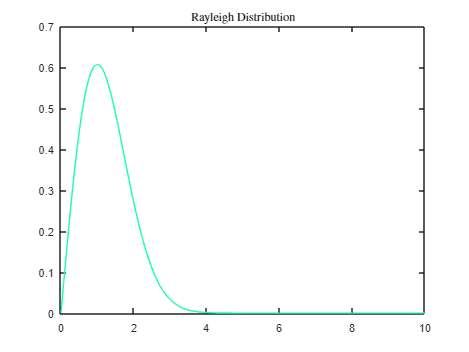

z = 0:0.01:10;
reyleigh = z.*exp(-(z.^2)/2);
plot (z,reyleigh,'Color',[0.1 1 0.7])
title('Rayleigh Distribution','Interpreter','latex')

## ب: تولید متغیرهای تصادفی نرمال 

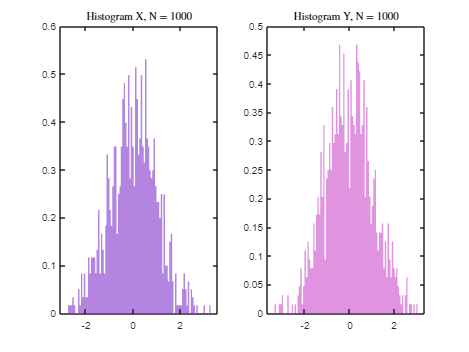

N = 1000;
subplot(1, 2, 1);
X =  normrnd(0, 1, [1, N]);
histogram(X, 'NumBins', 100,'FaceColor', [0.5 0.2 0.8], 'EdgeColor', 'none', 'Normalization', 'pdf');
title('Histogram X, N = 1000','Interpreter','latex');
%..................................................%

subplot(1, 2, 2);
Y =  normrnd(0, 1, [1, N]);
histogram(Y, 'NumBins', 100,'FaceColor', [0.8 0.3 0.8], 'EdgeColor', 'none', 'Normalization', 'pdf');
title('Histogram Y, N = 1000','Interpreter','latex');

## ج: تولید متغیر تصادفی رایلی

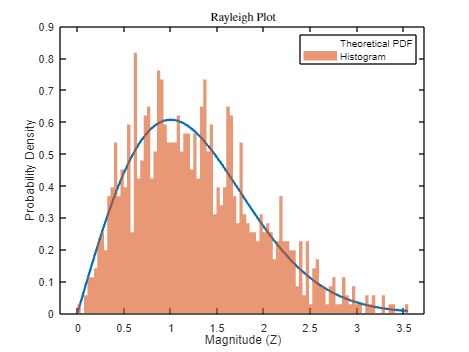

Z = sqrt(X.^2 + Y.^2);
x = linspace(0, max(Z), 100);
pdf = x ./ (1^2) .* exp(-x.^2 / (2 * 1^2));
figure;
plot(x, pdf, 'LineWidth', 2);
hold on;
histogram(Z, 'NumBins', 100, 'Normalization', 'pdf', 'EdgeColor', 'none');
hold off;
title('Rayleigh Plot','Interpreter','latex');
xlabel('Magnitude (Z)');
ylabel('Probability Density');
legend('Theoretical PDF', 'Histogram');

% Mean and  variance
[counts, edges] = histcounts(Z, 'Normalization', 'pdf');
centers = (edges(1:end-1) + edges(2:end)) / 2;
weighted_sum = sum(centers .* counts);
mean_Z = weighted_sum / sum(counts)

mean_Z = 1.2740

var_Z = (sqrt(sum((centers - mean_Z).^2 .* counts) / sum(counts)))^2

var_Z = 0.4428

##   N د : تاثیر افزایش 

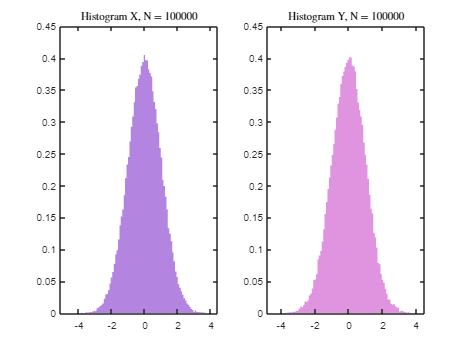

N1 = 100000;
subplot(1, 2, 1);
X1 = normrnd(0, 1, [1, N1]);
histogram(X1, 'NumBins', 100,'FaceColor', [0.5 0.2 0.8], 'EdgeColor', 'none', 'Normalization', 'pdf');
title('Histogram X, N = 100000','Interpreter','latex');

%..................................................%

subplot(1, 2, 2);
Y1 =  normrnd(0, 1, [1, N1]);
histogram(Y1, 'NumBins', 100,'FaceColor', [0.8 0.3 0.8], 'EdgeColor', 'none', 'Normalization', 'pdf');
title('Histogram Y, N = 100000','Interpreter','latex');

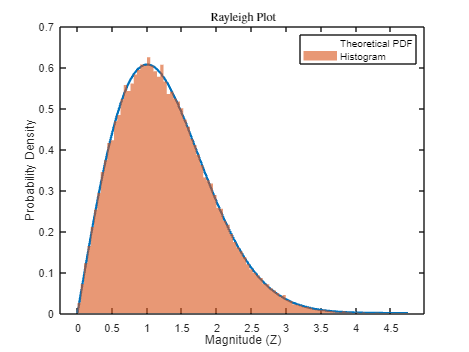

Z1 = sqrt(X1.^2 + Y1.^2);
x1 = linspace(0, max(Z1), 100);
pdf = x1 ./ (1^2) .* exp(-x1.^2 / (2 * 1^2));
figure;
plot(x1, pdf, 'LineWidth', 2);
hold on;
histogram(Z1, 'NumBins', 100, 'Normalization', 'pdf', 'EdgeColor', 'none');
hold off;
title('Rayleigh Plot','Interpreter','latex');
xlabel('Magnitude (Z)');
ylabel('Probability Density');
legend('Theoretical PDF', 'Histogram');


% Mean and varience
[counts, edges] = histcounts(Z1, 'Normalization', 'pdf');
centers = (edges(1:end-1) + edges(2:end)) / 2;
weighted_sum = sum(centers .* counts);
mean_Z1 = weighted_sum / sum(counts)

mean_Z1 = 1.2554

var_Z1 = (sqrt(sum((centers - mean_Z).^2 .* counts) / sum(counts)))^2

var_Z1 = 0.4305